## Time Delay in Dynamic Systems

Time delay is a shift in the effect of an input on an output dynamic response. A first-order linear system with time delay is:


$$\tau_p \frac{dy(t)}{dt} = -y(t) + K_p u\left(t-\theta_p\right)$$


has variables $y(t)$ and $u(t)$ and three unknown parameters.


$$K_p \quad \mathrm{= Process \; gain}$$



$$\tau_p \quad \mathrm{= Process \; time \; constant}$$



$$\theta_p \quad \mathrm{= Process \; dead \; time}$$


The time delay is expressed as a time shift in the input variable $u(t)$.


$$u\left(t-\theta_p\right)$$



$$y(t \lt \theta_p) = y(0)$$



$$y(t \ge \theta_p) = \left( e^{-\left(t - \theta_p \right) / \tau_p}\right) y(0) + \left( 1 - e^{-\left(t - \theta_p \right) / \tau_p} \right) K_p \Delta u$$


For a step change $\Delta u$, the analytical solution for a first-order linear system without time delay (*x(t)* = *y(t)* with $\theta_p=0$)


$$\tau_p \frac{dx(t)}{dt} = -y(t) + K_p u\left(t\right)$$
      

is


$$x(t) = K_p \left(1-\exp\left(\frac{-t}{\tau_p}\right)\right) \Delta u$$


With dead-time, the solution becomes:


$$y(t) = x \left( t-\theta_p \right) S \left( t-\theta_p \right)  = K_p \left( 1-  \exp\left(-\frac{ t-\theta_p } { \tau_p } \right) \right) \, \Delta u \, S \left( t-\theta_p \right)$$


where


$$S\left(t-\theta_p\right)$$


is a step function that changes from zero to one at $t=theta_p$.

**Analytic Solution Derivation with Laplace Transforms**

Start with the linear differential equation with time delay:


$$\tau_p \frac{dy(t)}{dt} = -y(t) + K_p u\left(t-\theta_p\right)$$


Perform a Laplace transform on each part of the equation (Use Laplace transfrom tables):


$$\mathcal{L}\left(\tau_p \frac{dy(t)}{dt}\right) = \tau_p \left(s Y(s) - y(0)\right)$$



$$\mathcal{L}\left(-y(t)\right) = -Y(s)$$



$$\mathcal{L}\left(K_p u\left(t-\theta_p\right)\right) = K_p U(s) e^{-\theta_p s}$$


If the input $U(s)$ is a step function of size $\Delta u$ then:


$$U(s) = \frac{\Delta u}{s}
$$


Combining all of the individual Laplace transforms, the equation in Laplace domain with zero initial condition *y(0)=0* is then:


$$\tau_p \, s \, Y(s) = -Y(s) + K_p \frac{\Delta u}{s} e^{-\theta_p s}$$


At this point, the equation is algebraic and can be solved for *Y(s)* by combining terms on each side:


$$\tau_p \, s \, Y(s) + Y(s) = K_p \frac{\Delta u}{s} e^{-\theta_p s}$$
    

and factoring out the *Y(s)* term:


$$Y(s) \left(\tau_p \, s + 1\right) = K_p \frac{\Delta u}{s} e^{-\theta_p s}$$


A final steps are to isolate *Y(s)* on the left side of the equation and perform an inverse Laplace transform to return to the time domain:


$$Y(s) = K_p \frac{\Delta u}{s\,\left(\tau_p \, s + 1\right)} e^{-\theta_p s}$$



$$\mathcal{L}^{-1}\left(Y(s)\right) = y(t) =  K_p \left( 1-\exp \left( 1-\frac{ \left( t-\theta_p \right) } { \tau_p } \right) \right) \, \Delta u \, S \left( t-\theta_p \right)
$$


clear
clc
clf

% Specify number of steps
ns = 100;

%define time points
t = linspace(0, ns/10, ns +1);

% Calculate Step Response
Kp = 2.5;
taup = 2.0;
thetap = 3.0;

y = 1; %placeholder variable
[pv, op] = calc_response(t, y, Kp, taup, thetap);

op =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


pv =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


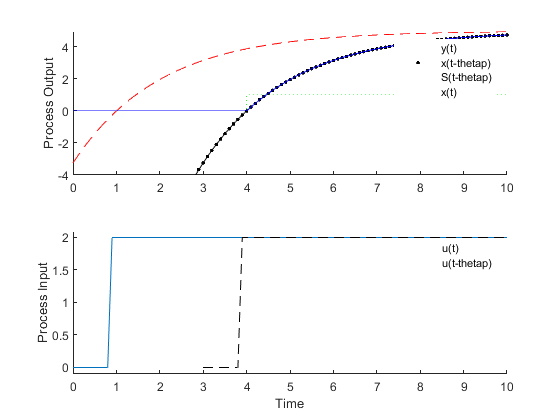


pv2 = zeros(size(t));
for i = 1:length(t)
    pv2(i) = Kp*(1-exp(-(t(i)-thetap-1)/taup))*2;
end

pv3 = zeros(size(t));
for i = 1:length(t)
    pv3(i) = Kp*(1-exp(-(t(i)-1)/taup))*2;
end

subplot(2,1,1)
hold on
p1 = plot(t, pv3, 'r--');
p2 = plot(t, pv2, 'k.-');
p3 = plot([0,4,4.0001,10],[0,0,1,1],'g:');
p4 = plot(t,pv,'b-');
ylim([-4,5])
ylabel('Process Output')
legend([p1, p2, p3, p4],{'y(t)','x(t-thetap)','S(t-thetap)', 'x(t)'})

subplot(2,1,2)
hold on
p5 = plot(t,op);
p6 = plot(t+3.0,op,'k--');
ylim([-0.1,2.1])
xlim([0,10])
ylabel('Process Input')
xlabel('Time')
legend([p5, p6], {'u(t)', 'u(t-thetap)'})

function dydt = process(t,y,u,Kp,taup)
    % Kp = process gain
    % taup = process time constant
    dydt = -y/taup + Kp/taup * u;
end

function [pv, op] = calc_response(t, y, Kp, taup, thetap)
    % t = time points
    % m = process model
    % specify number of steps
    ns = length(t)-1;
    delta_t = t(2)-t(1);

    % storage for recording values
    op = zeros(1,ns+1)  % controller output
    pv = zeros(1,ns+1)  % process variable

    % step input
    op(10:end)= 2;

    % Simulate time delay
    ndelay = int64(ceil(thetap / delta_t));

    
    % loop through time steps    
    for i = 1:ns
        % implement time delay
        iop = max([1,i-ndelay-1]); 
        % define solutiont time span
        ts = [delta_t*(i-1),delta_t*i];
        % solve differential equation
        [t, y] = ode45(@(t,y) process(t, y, op(iop), Kp, taup), ts, pv(i));
        pv(i+1) = y(end);
        
    end
end

